## **Extended braking stiffness estimation based on a switched observer for **ABS application.

Mainly we are going to analyis the switched observer design in the work [[1]](https://ieeexplore.ieee.org/document/6776392), which considers the design of an observer for the extended braking stiffness (XBS), In the context of hybrid anti-lock brake systems (ABS). In [1], they consider also the design of a closed-loop wheel-acceleration controller based on the observation of the extended braking stiffness. However, we focus only on the the observer design, which is based on Burckhardt’s tire model.  It worth mentioning that the XBS is one of the state variables of Burckhardt’s tire model.

### **Problem description**

The dynamics of the extended braking stiffness (XBS) using a simplified version of Burkhardt’s model is

$\[\begin{array}{l}
\frac{{d{z_1}}}{{dt}} = \frac{{ - a}}{{{v_x}(t)}}{z_1}{z_2} + bu(t)\\
\frac{{d{z_2}}}{{dt}} = \frac{c}{{{v_x}(t)}}{z_1}{z_2}\\
y = {z_1}
\end{array}\]$,

where $z_1=R\dot\omega-a_x$ and $z_2=\mu'(\lambda)$ (XBS) are the state variable, $y$ is the output, $u$ is the brake pressure derivative $a, b, c$ are constants, $R$ is the diameter of the tire, $\omega$ is its angular velocity, and $v_x$ is the The longitudinal speed of the tire, and $a_x$ is the vehicle’s longitudinal acceleration. For more information please see [[1]](https://ieeexplore.ieee.org/document/6776392).

The objective is to estimate the variable  $z_2=\mu'(\lambda)$ (XBS).

We consider that following values for the constants in the previous model and the constants that we might face in next steps:

vx=25;      %Vehicle longitudinal speed
Fz=700;     %Tire vertical load
I=1;        %Wheel inertia
R=0.3;      %Wheel radius
a=Fz*R^2/I; %Gain associated with load and inertia
gamma=25;   %Brake pad efficiency
b=gamma*R/I;%Gain associated to the brake pad
c=-20;      %XBS dynamics gain

The considered observer is:

$\[\begin{array}{l}
\frac{{d{{\hat z}_1}}}{{dt}} = \frac{{ - a}}{{{v_x}(t)}}{z_1}{{\hat z}_2} + bu(t) + \frac{{{k_1}({z_1})}}{{{v_x}}}{z_1}({z_1} - {{\hat z}_1})\\
\frac{{d{{\hat z}_2}}}{{dt}} = \frac{c}{{{v_x}(t)}}{z_1}{{\hat z}_2} + \frac{{{k_1}({z_1})}}{{{v_x}}}{z_1}({z_1} - {{\hat z}_1})
\end{array}\]$,

where the obserever gains $k_i(z1)$ (with $i\in\{1,2\}$) are chosen as follows

$\[{k_i}({z_1}) = \left\{ {\begin{array}{*{20}{c}}
{k_i^ + \;\;\;{\rm{when}}\;\;{z_1} > 0}\\
{k_i^ - \;\;\;{\rm{when}}\;\;{z_1} < 0}
\end{array}} \right.\]$.

Cosidering the observation error as $e_i=z_i-\hat z_i$ for $i\in\{1,2\}$, we get

$\[\frac{{de}}{{dt}} = \frac{{{z_1}}}{{{v_x}}}\left[ {\begin{array}{*{20}{c}}
{ - {k_1}({z_1})}&{ - a}\\
{ - {k_2}({z_2})}&c
\end{array}} \right]e\]$.

Then we consider a singular time-scale change:

$s(t)=\int_0^t{\frac{|z_1(\tau)|}{v_x(\tau)}d\tau}$.

For any function $\phi:R\to R$, we have

$\frac{d\phi}{ds}=\frac{d\phi}{dt}\frac{dt}{ds}=\frac{d\phi}{dt}\frac{v_x}{|z_1(t)|}$.

So, we obtain the following switched system 

$\[\frac{{de}}{{ds}} = \left\{ {\begin{array}{*{20}{c}}
{{A_p}e(s) = \left[ {\begin{array}{*{20}{c}}
{ - k_1^ + }&{ - a}\\
{ - k_2^ + }&c
\end{array}} \right]e(s)\;\;\;{\rm{when  }}\;\;\;{z_1} > 0}\\
{{A_m}e(s) = \left[ {\begin{array}{*{20}{c}}
{k_1^ - }&a\\
{k_2^ - }&{ - c}
\end{array}} \right]e(s)\;\;\;\;\;\;{\rm{when  }}\;\;\;{z_1} < 0}
\end{array}} \right.\]$.

### **Stability analysis for arbitrary switchings**  

1- we can see that the matrices $A_p,A_m$ are Hurwitz when the roots of the polynomials ($\[{s^2} + (k_1^ +  - c)s - ck_1^ +  - ak_2^ + \]$), ($\[{s^2} + (c - k_1^ - )s - ck_1^ -  - ak_2^ - \]$) are located in the left half of the complex plane. Comparing with the known forma for the Hurwitz second ordered polynomials ($s^2+2\xi\omega_0s+\omega_0^2$), we find that  the matrices $A_p,A_m$ are Hurwitz when 


$$\[\begin{array}{l}
ck_1^ +  + ak_2^ +  < 0,k_1^ +  > c \Rightarrow k_1^ +  > \max (c,\frac{{ - ak_2^ + }}{c})\\
ck_1^ -  + ak_2^ -  < 0,c > k_1^ -  \Rightarrow c > k_1^ -  > \frac{{ - ak_2^2}}{c}
\end{array}\]$$


2- **In the particular case** $c=0$, we get


$$\[\begin{array}{l}
k_1^ +  > 0,\\
k_2^ +  < 0,\\
k_1^ -  < 0,\\
k_2^ -  < 0.
\end{array}\]$$


Now to analyze the behavior of our switched system for arbitrary commutation signals propused by [[2]](https://hal.archives-ouvertes.fr/hal-00323682/document). (please check their results which provide a Full characterization for bi-dimensional two-mode LTI switching systems).

We have:


$$\Gamma(A_p,A_m)=\frac{1}{2}(\rm{tr}(A_p)\rm{tr}(A_m)-\rm{tr}(A_pA_m))=\frac{1}{2}(-k_1^+k_1^--(-k_1^+k_1^--ak_2^+-ak_2^-))=\frac{a}{2}(k_2^++k_2^-)$$



$$-\sqrt{\det(A_p)\det(A_m)}=-\sqrt{(-ak_2^+)(-ak_2^-)}=-a\sqrt{k_2^+k_2^-}$$


It reasonable to consider only the case when both matrices  $A_p,A_m$  are Hurwitz ($\[k_1^ +  > 0,\,\,k_2^ +  < 0,\,\,k_1^ -  < 0,\,\,k_2^ -  < 0\]$). Taking this into account we can see that there is two cases

Case 1: $\[k_2^ +  = k_2^ -  \Rightarrow \frac{1}{2}(k_2^ +  + k_2^ - ) =  - \sqrt {k_2^ + k_2^ - }  \Rightarrow \Gamma ({A_p},{A_m}) =  - \sqrt {\det ({A_p})\det ({A_m})} \]
$

which leads to  the system is **uniformly stable** but not globally uniformly asymptotically stable. 

Case 2: $\[k_2^ +  \ne k_2^ -  \Rightarrow  - \frac{1}{2}(k_2^ +  + k_2^ - ) > \sqrt {k_2^ + k_2^ - }  \Rightarrow \Gamma ({A_p},{A_m}) <  - \sqrt {\det ({A_p})\det ({A_m})} \]$

and the system is **unbounded**. Here we used the the inequality of arithmetic and geometric means.

3-  Now we will consider a choice of the gains $k^ +, k^ -$ for which non-bounded trajectories are ensured.

k1p=1;
k1n=-1;
k2p=-2;
k2n=-3;
c=0;

We will study the eigen values of the pencil $M=\{(1-\epsilon)A_p+\epsilon A_m,\epsilon\in[0,1]\}$

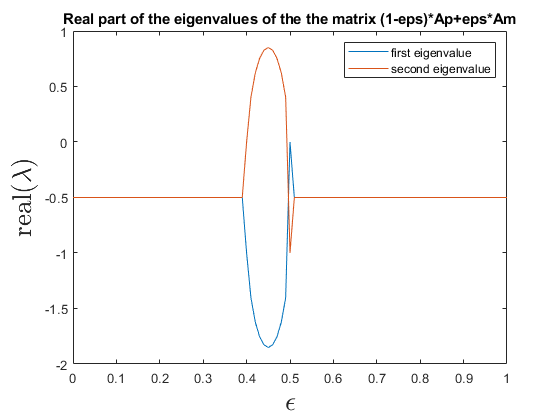

Ap=[-k1p -a;-k2p c];
Am=[k1n a;k2n c];
re1=zeros(101,1);
im1=zeros(101,1);
re2=zeros(101,1);
im2=zeros(101,1);
i=1;
for eps=0:0.01:1
    A=(1-eps)*Ap+eps*Am;
    e=eig(A);
    re1(i)=real(e(1));
    re2(i)=real(e(2));
    im1(i)=imag(e(1));
    im2(i)=imag(e(2));
    i=i+1;
end
figure();
plot([0:0.01:1],re1);
hold on;
plot([0:0.01:1],re2);
xlabel('$\epsilon$', 'Interpreter', 'LaTeX','FontSize',20);
ylabel('real$(\lambda)$', 'Interpreter', 'LaTeX','FontSize',20);
legend('first eigenvalue','second eigenvalue');
title('Real part of the eigenvalues of the the matrix (1-eps)*Ap+eps*Am');

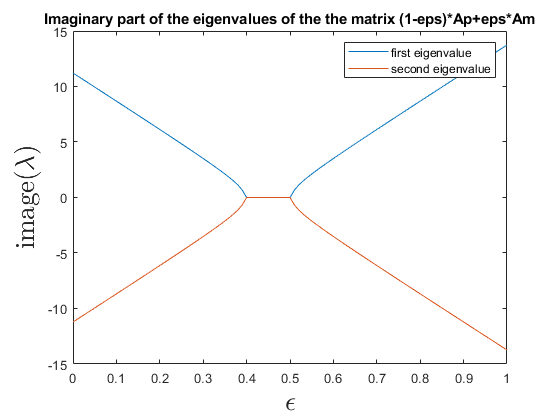

figure();
plot([0:0.01:1],im1);
hold on;
plot([0:0.01:1],im2);
xlabel('$\epsilon$', 'Interpreter', 'LaTeX','FontSize',20);
ylabel('image$(\lambda)$', 'Interpreter', 'LaTeX','FontSize',20);
legend('first eigenvalue','second eigenvalue');
title('Imaginary part of the eigenvalues of the the matrix (1-eps)*Ap+eps*Am');

From the figure, in which the real part of the eigenvalues is shown, we can see that for $
\epsilon>0.5$ and $\epsilon<0.39$ the real parts of the eignvalues are negative. (The inequalities are found roughly from the figure).

4- We will check the ability to stabilize the system with a pulse-width modulated switching signal that has a duty ratio that corresponds $\epsilon$.

eps=0.61;

Run this matlab file ([Simulink](matlab:open('Stabilizability_by_pulse_width_modulated_switching'))) for different values of the paramter $\epsilon$.

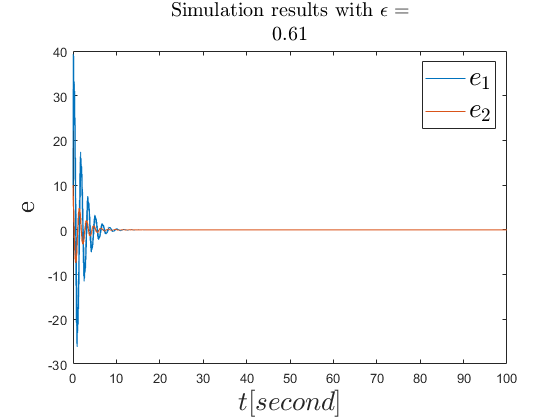

figure();
plot(out.e(:,1),out.e(:,2),out.e(:,1),out.e(:,3));
legend('$e_1$','$e_2$', 'Interpreter', 'LaTeX','FontSize',20);
xlabel('$t[second]$', 'Interpreter', 'LaTeX','FontSize',20);
ylabel('e', 'Interpreter', 'LaTeX','FontSize',20); 
title(['Simulation results with $\epsilon=$',string(eps)], 'Interpreter', 'LaTeX','FontSize',15);

We can see that the results correspnds to the one found when we studied the eigenvalues of the matrix ($(1-\epsilon)A_p+\epsilon A_m,\epsilon
$). That is the system is stable for $
\epsilon>0.5$ and $\epsilon<0.39$ and not stable otherwise.

### **Imposing a dwell-time between switchings**  

5- Now we consider the the case when the gains $k^ +, k^ -$ for which the origin of the system is stable for an arbitrary switching signal. Our objective is to find a (non-strict) common Lyapunov function for matrices $A_p$ and $A_m$. To do so, we will solve the following equations


$$\[\begin{array}{l}
A_p^TP + P{A_p} =  - Q\\
A_m^TP + P{A_m} =  - Q
\end{array}\]$$


where $P=P^T>0$, and $Q=C^TC$, with $C=[1\;\;0]$.

k1p=1;
k1n=-1;
k2p=-2;
k2n=-2;
c=0;
Ap=[-k1p -a;-k2p c];
Am=[k1n a;k2n c];
C=[1 0];
Q=C'*C;
syms p11 p12 p22
P=[p11 p12;p12 p22];
sol=solve([Ap'*P+P*Ap==-Q,Am'*P+P*Am==-Q],[p11,p12,p22]);
P=double([sol.p11 sol.p12;sol.p12 sol.p22])

P =     0.5000         0
         0   15.7500


As we are able to solve this equation and the solution is found then there exist a nonstrict common quadratic Lyapunov function to all modes. Then the dynamic of the observer is uniformly globally stable. (Please check [[3]](https://ieeexplore.ieee.org/document/1284711)).

6- From the other side we can find that:

rank([C;C*Ap])

ans = 2

rank([C;C*Am])

ans = 2

The previous results shows that the pairs $(A_p,C)$ and $(A_m,C)$ are observable then given any dwell time $T>0$, the dynamic of the observer is globally exponentially stable. (Please check [[3]](https://ieeexplore.ieee.org/document/1284711)).

Note: We refer to this minimum time between two consecutive switching times as the dwell time.  

7- We will check the behavior  of the observer with a pulse-width modulated switching signal that has a duty ratio that corresponds $\epsilon$.

eps=0.32;

Run this matlab file ([Simulink](matlab:open('Stabilizability_by_pulse_width_modulated_switching'))) for different values of the paramter $\epsilon$.

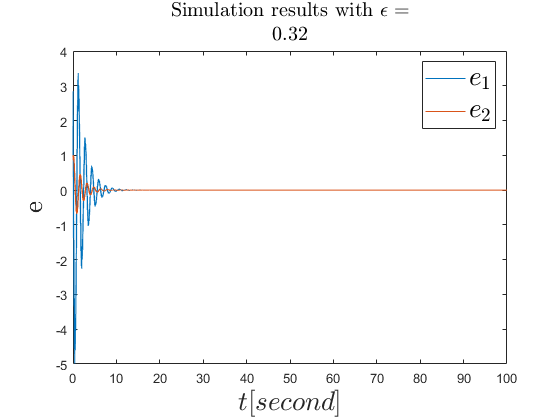

figure();
plot(out.e(:,1),out.e(:,2),out.e(:,1),out.e(:,3));
legend('$e_1$','$e_2$', 'Interpreter', 'LaTeX','FontSize',20);
xlabel('$t[second]$', 'Interpreter', 'LaTeX','FontSize',20);
ylabel('e', 'Interpreter', 'LaTeX','FontSize',20); 
title(['Simulation results with $\epsilon=$',string(eps)], 'Interpreter', 'LaTeX','FontSize',15);

We can see that the errors converge to zero, which results from the fact that we use a pulse-width modulated switching signal, which has a dwell time selected by the duty cycle (dwell time equal to the smaller time the signal stay off or on).